Q1)

Implementing a Jeffersonian Grid network for analysis

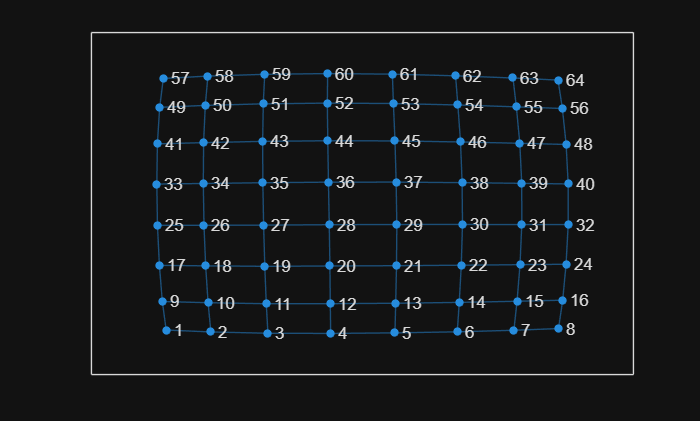

n = 10;     % number of nodes (+2, matlab removes circumfrence nodes)
L = 0.1;    % length of edges (roads)
A = numgrid('S', n);    % grid of nodes
A = -L*delsq(A);    % convert to sparse adjacency matrix
% Note the above matrix is actually dense for this example
G = graph(A, 'omitselfloops');
h = plot(G);

figure
plot(G)

% adding euclidean coordinates for nodes
% h.XData = L*floor((0:(n-2)^2-1)/10);
% h.YData = L*rem((0:(n-2)^2-1), 10);


a)

Some information about the graph

G.neighbors(5)      % display neighbours of node 5

ans =      4
     6
    13


G.degree(22)        % display degree (length of neighbours)

ans = 4

G.centrality("degree")  % lists centrality of all nodes

ans =      2
     3
     3
     3
     3
     3
     3
     2
     3
     4
     4
     4
     4
     4
     4


b)

some path finding trickery

G.shortestpath(1, 64)   % display shortest path between 2 nodes as a list of nodes visited

ans =      1     2     3     4     5     6     7     8    16    24    32    40    48    56    64


[p, d, edgepath] = G.shortestpath(3, 41)

p =      3     2     1     9    17    25    33    41


d = 0.7000

edgepath =      3     1     2    17    32    47    62


% p: path between nodes,
% d: total edge length traversed
% edgepath: edges of path traversed


c)

computing the shortest paths between a set of origin and destination nodes

o = [1, 14, 27, 63];      % origin/destination nodes

% see pathFinder.m for how it works
paths = pathFinder(G, o)

Total elapsed time: 0.13895
Elapsed time per path: 0.0086844


paths = 16×4 table
    EndNodes                     Nodes                                     Edges                     Length
    _________    ______________________________________    ______________________________________    ______

    {[  1 1]}    {[                                 1]}    {1×0 double                          }       0  
    {[ 1 14]}    {[                    1 2 3 4 5 6 14]}    {[                      1 3 5 7 9 12]}     0.6  
    {[ 1 27]}    {[                    1 2 3 11 19 27]}    {[                       1 3 6 21 36]}     0.5  
    {[ 1 63]}    {[1 2 3 4 5 6 7 15 23 31 39 47 55 63]}    {[1 3 5 7 9 11 14 29 44 59 74 89 104]}     1.3  
    {[ 14 1]}    {[                    14 6 5 4 3 2 1]}    {[                      12 9 7 5 3 1]}     0.6  
    {[14 14]}    {[                                14]}    {1×0 double                  

Q2.a)

Perturbing the original graph and having another gander

rng default;

n = 10;     % number of nodes (+2, matlab removes circumfrence nodes)
mu = 1;    % typical edge length
L = rand([(n-2)^2, 1]) * 2 * mu

L =     1.6294
    1.8116
    0.2540
    1.8268
    1.2647
    0.1951
    0.5570
    1.0938
    1.9150
    1.9298
    0.3152
    1.9412
    1.9143
    0.9708
    1.6006


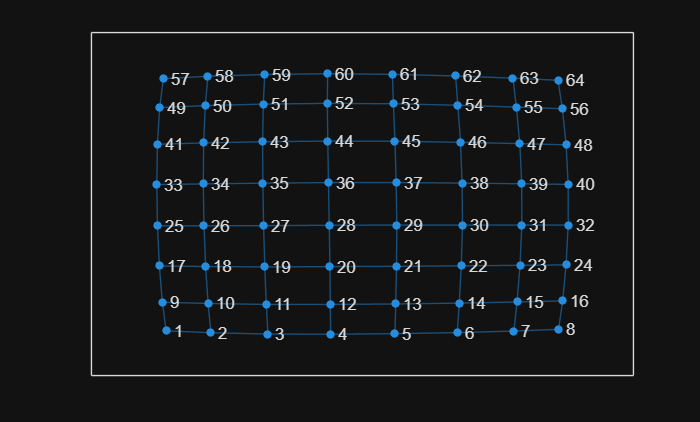

A = numgrid('S', n);    % grid of nodes
A = -L.*delsq(A);    % convert to sparse adjacency matrix
% Note the above matrix is actually dense for this example
G = graph(A, 'omitselfloops', 'upper');
h = plot(G);

% ive broken the plot :(
figure
plot(G)

% adding euclidean coordinates for nodes
% h.XData = L.*floor((0:(n-2)^2-1)/10);
% h.YData = L.*rem((0:(n-2)^2-1), 10);


Gander time

o = [1, 14, 27, 63]

o =      1    14    27    63


paths = pathFinder(G, o)

Total elapsed time: 0.019955
Elapsed time per path: 0.0012472


paths = 16×4 table
    EndNodes                      Nodes                                      Edges                     Length
    _________    _______________________________________    _______________________________________    ______

    {[  1 1]}    {[                                  1]}    {1×0 double                           }         0
    {[ 1 14]}    {[                     1 2 3 4 5 6 14]}    {[                       1 3 5 7 9 12]}    6.9816
    {[ 1 27]}    {[                     1 2 3 11 19 27]}    {[                        1 3 6 21 36]}    5.5946
    {[ 1 63]}    {[1 2 3 4 5 6 14 22 30 38 46 54 55 63]}    {[1 3 5 7 9 12 27 42 57 72 87 101 104]}    10.543
    {[ 14 1]}    {[                     14 6 5 4 3 2 1]}    {[                       12 9 7 5 3 1]}    6.9816
    {[14 14]}    {[                                 14]}    {1×0 double   